% editing figs
fig = openfig('IntersectNEintermediate.fig')

fig =   Figure (88: Figure) with properties:

      Number: 88
        Name: 'Figure'
       Color: [1 1 1]
    Position: [200 117 1200 1200]
       Units: 'pixels'

  Show all properties


axObjs = fig.Children;
dataObjs = axObjs.Children

dataObjs =   4×1 graphics array:

  Scatter
  Scatter
  ImplicitFunctionSurface
  ImplicitFunctionSurface


% Xnv = dataObjs(1).XData;
% Ynv = dataObjs(1).YData;
% Znv = dataObjs(1).ZData;
% Xne = dataObjs(2).XData;
% Yne = dataObjs(2).YData;
% Zne = dataObjs(2).ZData;

its = cell(2, 1);
for i = 1:2
    intersections = [];
    X = dataObjs(i).XData;
    Y = dataObjs(i).YData;
    Z = dataObjs(i).ZData;
    for j = 1:length(X)
        if abs(dataObjs(3).Function(X(j), Y(j), Z(j))) < 0.001
            intersections = [intersections, [X(j);Y(j);Z(j)]];
        end
        if abs(dataObjs(4).Function(X(j), Y(j), Z(j))) < 0.001
            intersections = [intersections, [X(j);Y(j);Z(j)]];
        end 
    end
    its{i} = intersections;
end

its

its = 2×1 cell array
    {3×2  double}
    {3×34 double}


dataObjs(3)

ans =   ImplicitFunctionSurface with properties:

     Function: @(x,y,z)(1-(x.^2+y.^2+z.^2)).*z-2.*x.*y+k*(1+(x.^2+y.^2+z.^2)).^2
       XRange: [-5 5]
       YRange: [-5 5]
       ZRange: [-5 5]
    EdgeColor: 'none'
    LineStyle: '-'
    FaceColor: 'interp'

  Show all properties


k = 0.13

k = 0.1300

k = 0.249

k = 0.2490

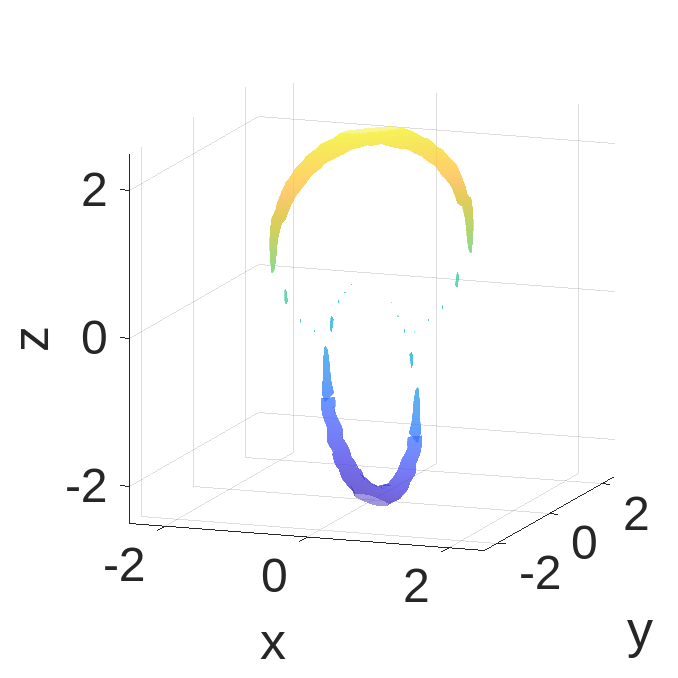

surfaceEq = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y - k * (1+(x.^2+y.^2+z.^2)).^2;
surfaceEq1 = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y + k * (1+(x.^2+y.^2+z.^2)).^2;
% Plot the surface using fimplicit3
figure("Position", [200, 200, 1000, 1000])
hold on
xr = 5;
yr = 5;
zr = 5;
falpha = 0.5;
fimplicit3(surfaceEq, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
fimplicit3(surfaceEq1, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
xlabel('x')
ylabel('y')
zlabel('z')
% title('Intermediate entanglement')
grid on
axis equal

a = linspace(0,2*pi,100);
r = sqrt(2);
x1 = r*cos(a)/sqrt(2);
y1 = -r*cos(a)/sqrt(2);
z1 = r*sin(a)-1;
%plot3(x1, y1, z1, 'LineWidth', 2, 'Color', 'k');
x2 = r*cos(a)/sqrt(2);
y2 = r*cos(a)/sqrt(2);
z2 = r*sin(a)+1;
%plot3(x2, y2, z2, 'LineWidth', 2, 'Color', 'k');
xlabel('x', FontSize=36);
ylabel('y', FontSize=36);
zlabel('z', FontSize=36);
% scatter3(Bsat(:, 1), Bsat(:, 2), Bsat(:, 3), 'filled', 'o', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b')
% scatter3(Bunsat(:, 1), Bunsat(:, 2), Bunsat(:, 3), 'r.')
xlim([-5,5]/2)
ylim([-5,5]/2)
zlim([-5,5]/2)
nvdat = its{1};
nedat = its{2};


% scatter3(nvdat(1,:),nvdat(2,:),nvdat(3,:), 80, 'filled', 'o', 'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'red')
% scatter3(nedat(1,:),nedat(2,:),nedat(3,:), 120, 'filled', 'o', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'blue')
view([20,12])

ax = gca;
ax.XAxis.FontSize = 36;
ax.YAxis.FontSize = 36;
ax.ZAxis.FontSize = 36;

% The dataset for the Nash local minima
fig = openfig('IntersectNEMES.fig');
axObjs = fig.Children;
dataObjs = axObjs.Children;
nlm = [dataObjs(2).XData; dataObjs(2).YData; dataObjs(2).ZData];
% disp(size(nash_local_minima))
eps = 1e-2

eps = 0.0100

kset = linspace(0, 0.25, 100);
payoffs = zeros(50, 2);
for i = 1:length(kset)
    [eq_state, payoff] = get_eq_payoff(kset(i), nlm, eps);
    payoffs(i, :) = payoff;
end


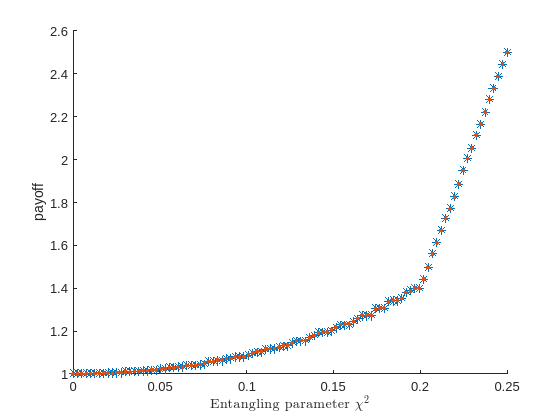

figure()
scatter(kset, payoffs(:, 1), Marker="*")
hold on
scatter(kset, payoffs(:, 2), Marker=".")
ylabel("payoff")
xlabel('Entangling parameter $\chi^2$', Interpreter='latex')

function [eq_states, payoff] = get_eq_payoff(k, nlm, eps)
    % Two surfaces for the orbit under SU(2)xSU(2) action
    sp = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y - k * (1+(x.^2+y.^2+z.^2)).^2;
    sm = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y + k * (1+(x.^2+y.^2+z.^2)).^2;
    % find the minimal distance between the surfaces and the datapoints
    % between
    dist_p = abs(sp(nlm(1, :), nlm(2, :), nlm(3, :)));
    dist_m = abs(sm(nlm(1, :), nlm(2, :), nlm(3, :)));

    min_dist = zeros(size(dist_p));
    for i = 1:size(dist_m, 2)
        min_dist(i) = min(dist_p(i), dist_m(i));
    end

    % find the point with the minimal distance as the solution to the QPD
    [min_d, min_d_ind] = mink(min_dist, 8);
    assert(min_d(2) < eps)

    eq_states = nlm(:, min_d_ind);
    % convert the equilibrium state to the 4D representation

    eq_states = inverse_stereo_project(eq_states);
    payoff = [max(diag(eq_states' * diag([3, 0, 5, 1]) * eq_states)), max(diag(eq_states' * diag([3, 5, 0, 1]) * eq_states))];
end

function Y = inverse_stereo_project(X)
    denom = 1 + sum(X.^2, 1); % 1 + x^2 + y^2 + z^2
    Y = zeros(4, 8);
    % Compute S3 coordinates
    Y(1, :) = (1 - sum(X.^2, 1)) ./ denom;  % W component
    Y(2, :) = 2 * X(1, :) ./ denom;          % X component
    Y(3, :) = 2 * X(2, :) ./ denom;          % Y component
    Y(4, :) = 2 * X(3, :) ./ denom;          % Z component
end







